# Spectral correction for extreme value analysis: Application to NORA3

This MATLAB Live Script corrects the underestimation of NORA3 extreme wind speeds using a spectral-slope adjustment method described in Bastine et al. [1]. In this example, approximately 50 years of wind speed data from the Slåtterøy lighthouse (Norway) are used. The same method can be applied for different mesoscale wind speed databases.

For this coastal site, extreme value estimates from NORA3 already agree reasonably well with mast measurements, and the agreement is already notably closer than in the offshore case studied in [1].

The spectral correction is based on identifying and adjusting the slope of the power spectral density (PSD) in a specific subrange, effectively applying a deconvolution. In this range, the PSD slope is expected to follow a −5/3 power law.

Bastine et al. [1] used a minimum frequency of 1 / (1.5 days) for their correction. For Slåtterøy lighthouse, that choice leads to significant overcorrection. Here, frequencies between 1 / (12 hours) and 1 / (6 hours) are found to yield the best results.

**Workflow:**

- Load mast and NORA3 data from NetCDF files.

- Compute PSDs for mast and NORA3 series, with NaN handling.

- Identify inertial subrange frequency bounds.

- Apply spectral slope correction to NORA3.

- Compare PSDs before and after correction with mast data.

- Perform extreme value analysis (GEV fit, 100-year return values).

- Plot a time series comparison for a selected month.

**Reference:**

[1] Bastine, D., Larsén, X., Witha, B., Dörenkämper, M., & Gottschall, J. (2018). Extreme winds in the new European wind atlas. *Journal of Physics: Conference Series*, 1102, 012006. IOP Publishing.

## Read data from netcdf files

set(0, 'DefaultFigureRenderer', 'painters');

% Read NORA3 data
time_NORA3 = datetime(1970,1,1) + seconds(ncread('NORA3_lighthouse_subset.nc','time_seconds'));
z = double(ncread('NORA3_lighthouse_subset.nc','height'));
U_NORA3 = double(ncread('NORA3_lighthouse_subset.nc','U'));

% Read measured wind speed data from lighthouse
time_mast0 = datetime(1970,1,1) + seconds(ncread('slatteroy_fyr_wind_speed.nc','time'));
u_mast0 = (ncread('slatteroy_fyr_wind_speed.nc','obs_corr'));

time_mast = min(time_mast):hours(1):max(time_mast);

u_mast = interp1(time_mast0,u_mast0,time_mast);

% remove NANs from NORA3
time_NORA3(isnan(U_NORA3(:,1))) = [];
U_NORA3(isnan(U_NORA3(:,1)),:) = [];

## Correction of NORA3 data with spectral slope identification

% let's focus on data with higher quality (post 1986)
ind_mast = find(time_mast>=datetime(1986,1,1));
ind_NORA3 = find(time_NORA3>=datetime(1986,1,1));

fs = 1/3600; % in Hz for the mast
[Sm,fm]=pwelch(detrend(inpaint_nans(u_mast(ind_mast),4)),[],[],[],fs);
[S_nora,f_nora]=pwelch(detrend(U_NORA3(ind_NORA3,1)),[],[],[],fs);

% we identify the spectral slope for periods between 12h and 3 h
fmin = 1/(12*3600); % 12 h
fmax = 1/(6*3600); % 6 hours

% Correction of NORA3 data
u_corrected = correctSpectrumSlope(U_NORA3(:,1), fs, fmin,fmax);


## Power spectral density visualization

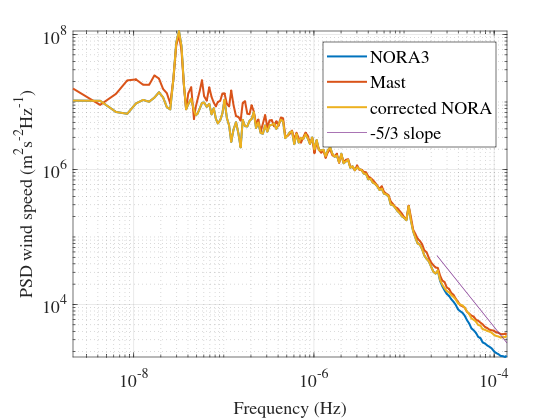


[Sn_c,fn_c]=pwelch(detrend(u_corrected(ind_NORA3)),[],[],[],fs);

% smooth psd for visualization purpose
M=200;
newF0 = logspace(log10(fm(2)*0.8),log10(fm(end)*1.1),M);
[Sm_bin,fm_bin] = binAveraging(Sm,fm,'newX',newF0);

newF0 = logspace(log10(fm(2)*0.8),log10(fm(end)*1.1),M);
[Sn_bin,fn_bin] = binAveraging(S_nora,f_nora,'newX',newF0);

newF0 = logspace(log10(fm(2)*0.8),log10(fm(end)*1.1),M);
[Sn_c_bin,fn_c_bin] = binAveraging(Sn_c,fn_c,'newX',newF0);

%
clf;close all;
loglog(fn_bin,Sn_bin,fm_bin,Sm_bin,fn_c_bin,Sn_c_bin,'linewidth',1.5);
axis tight
hold on
plot([fmin fs/2],0.001*[fmin fs/2].^(-5/3))
legend('NORA3','Mast','corrected NORA','-5/3 slope')
grid on
xlabel('Frequency (Hz)')
ylabel('PSD wind speed (m^2s^{-2}Hz^{-1})')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## Extreme value with and without correction

clf;close all
method = 'Gumbel';
returnPeriod = 50;
yearStart= 1986;
yearEnd = 2024;
N1 = numel(yearStart:yearEnd);

clc;

figure
tiledlayout(1,3,"TileSpacing","tight")

maxU = nan(N1,1);ll=1;
for ii=yearStart:yearEnd
    indYear = find(time_mast>=datetime(ii,1,1) & time_mast<datetime(ii+1,1,1));
    maxU(ll) = max(u_mast(indYear));
    ll=ll+1;
end
nexttile
[para,U50] = fitGEV(maxU,'method',method,'dataPlot',1,'returnPeriod',returnPeriod);

50-year hourly wind velocity is 31.2 m/s (based on 39 years of data) 


label('Mast',0.03,0.98,'verticalalignment','top');
ylim([15 35])
legend off

maxU = nan(N1,1);ll=1;
for ii=yearStart:yearEnd
    indYear = find(time_NORA3>=datetime(ii,1,1) & time_NORA3<datetime(ii+1,1,1));
    maxU(ll) = max(U_NORA3(indYear,1));
    ll=ll+1;
end

nexttile
[para,U50] = fitGEV(maxU,'method',method,'dataPlot',1,'returnPeriod',returnPeriod);

50-year hourly wind velocity is 30.0 m/s (based on 39 years of data) 


label('NORA3',0.03,0.98,'verticalalignment','top');
ylabel('')
set(gca,'yticklabels',[])
legend off
ylim([15 35])
maxU = nan(N1,1);ll=1;
fs = 1/3600;

for ii=yearStart:yearEnd
    indYear = find(time_NORA3>=datetime(ii,1,1) & time_NORA3<datetime(ii+1,1,1));
    maxU(ll) = max(u_corrected(indYear),[],'omitnan');
    ll=ll+1;
end

nexttile
[para,U50] = fitGEV(maxU,'method',method,'dataPlot',1,'returnPeriod',returnPeriod);

50-year hourly wind velocity is 31.0 m/s (based on 39 years of data) 


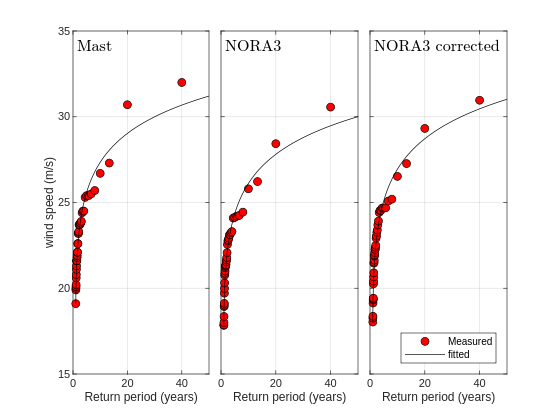

label('NORA3 corrected',0.03,0.98,'verticalalignment','top');
ylabel('')
set(gca,'yticklabels',[])
ylim([15 35])


set(gcf,'color','w')
% set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')

## Time series visualization 

indT=find(time_NORA3>=datetime(2011,12,1) & time_NORA3<datetime(2011,12,30));
indT_mast=find(time_mast>=datetime(2011,12,1) & time_mast<datetime(2011,12,30));

clf;close all
figure
plot(time_NORA3(indT),u_corrected(indT))
hold on
plot(time_NORA3(indT),U_NORA3(indT,1))

plot(time_mast(indT_mast),u_mast(indT_mast))
axis tight
legend('NORA3  corrected','NORA3','mast')
ylabel('Wind speed (m s^{-1})')
set(gcf,'color','w')
set(findall(gcf,'-property','FontSize'),'FontSize',14,'FontName','Times')
